# Sample 12-2

## 画像復元

フィルタ補正逆投影法 (FBP)

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image restoraton

Filtered backprojection (FBP)

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all

nSlices = 180;
lambda = 10^-4

lambda = 1.0000e-04

## 画像生成

(Image generation)

- $u(\mathbf{p}), \mathbf{p}\in\mathbb{R}^2$: 原画像 (Original image)

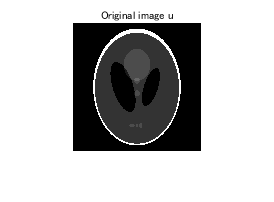

u = phantom(128); 
figure(1)
imshow(u)
title('Original image u')

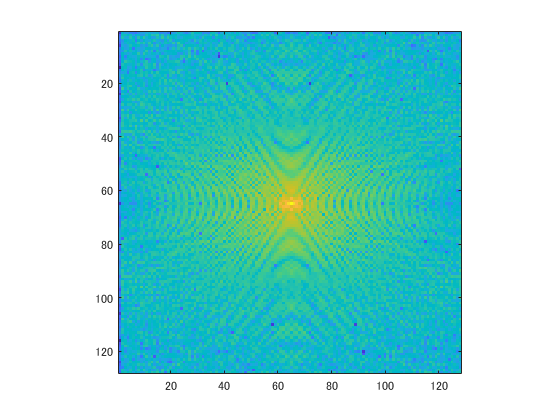

U = fftn(u);
figure(2)
imagesc(fftshift(20*log10(abs(U))))
%axis off
axis square

Perform a Radon transform of the image.

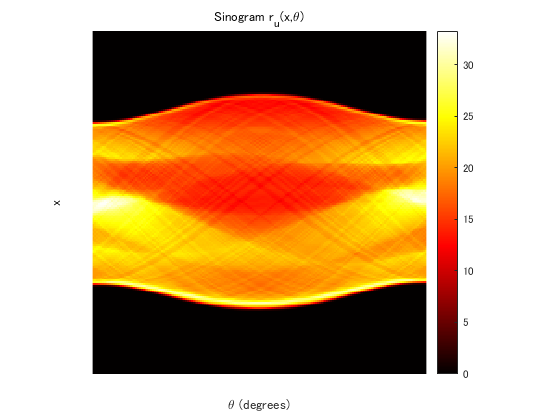

thetaset = linspace(0,180-180/nSlices,nSlices);
[r,p] = radon(u,thetaset);

figure(3)
imshow(r,[],'Xdata',thetaset,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('x')
title('Sinogram r_u(x,\theta)')
colormap(gca,hot), colorbar

iptsetpref('ImshowAxesVisible','off')

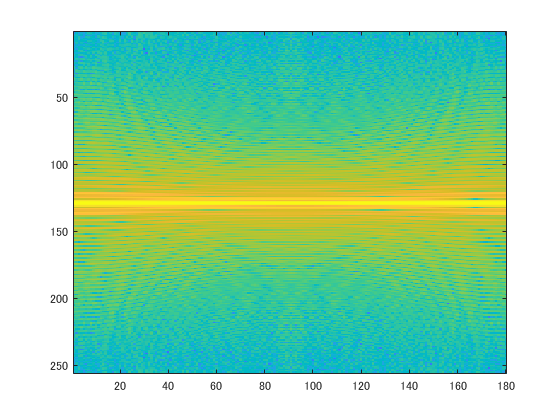

nPoints = 2^nextpow2(max([size(U,1) length(p)]));
rc = circshift(padarray(r,nPoints-size(r,1),'post'),p(1));
R = fft(rc,nPoints,1);

figure(4)
imagesc(fftshift(20*log10(abs(R)),1))

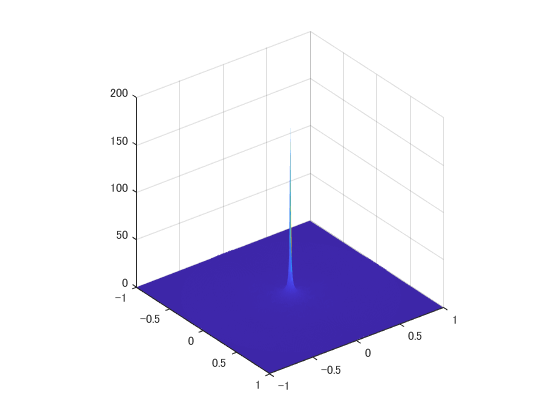

SR = zeros(nPoints+1);
SS = zeros(nPoints+1);
S0 = zeros(nPoints+1);
S1 = S0;
S1(1,:) = 1;
for iSlice = 1:length(thetaset)
    theta = thetaset(iSlice);
    Si = S0;
    Si(1,:) = [R(:,iSlice).' 0];
    SR = SR + imrotate(fftshift(Si),theta,'crop');
    SS = SS + imrotate(fftshift(S1,1),theta,'crop');
end
SR = ifftshift(SR(1:end-1,1:end-1));
SS = ifftshift(SS(1:end-1,1:end-1));

figure(5)
%imagesc(SS)
[k0,k1] = ndgrid(linspace(-1,1-1/nPoints,nPoints));
surf(k0,k1,fftshift(SS),'EdgeColor','none')
%axis off
axis square
ax = gca;
ax.YDir = 'reverse';

max(SS(:))

ans = 180

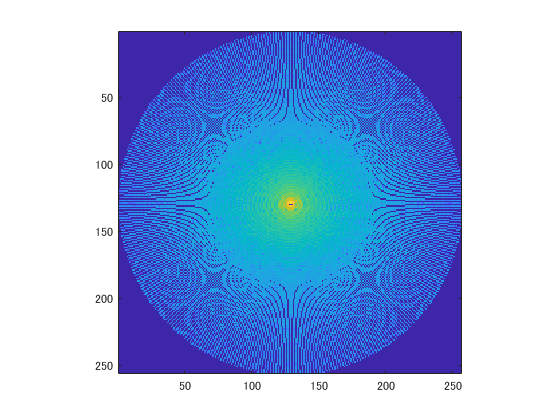


figure(6)
imagesc(fftshift(20*log10(abs(SR))))
%axis off
axis square

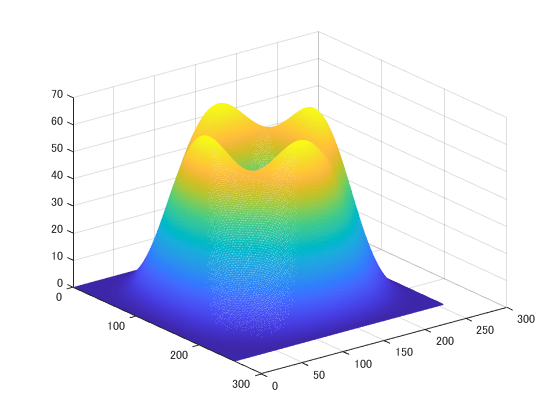

g0 = fspecial('sobel');
g1 = g0.';
GG = abs(fftn(g0,nPoints*[1 1])).^2+abs(fftn(g1,nPoints*[1 1])).^2;
LL = nPoints*GG;
figure(7)
mesh(fftshift(GG))
ax = gca;
ax.YDir = 'reverse';

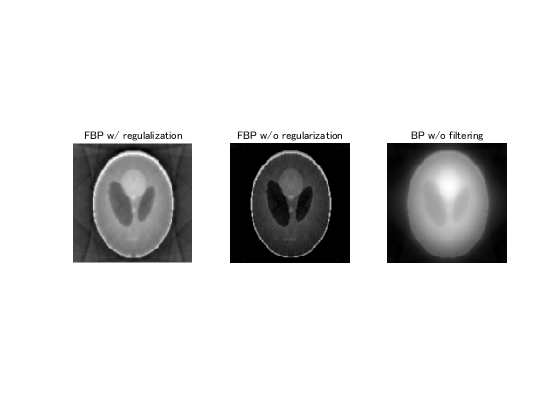

figure(8)
% FBP w/ regulalization
Ur = SR./(SS+lambda*LL+eps);
ur = circshift(real(ifft2(Ur)),size(u)/2);
ur = ur(1:size(u,1),1:size(u,2));
subplot(1,3,1)
imshow(ur,[])
title('FBP w/ regulalization')
% FBP w/o regulalization
Uo = SR./(SS+eps);
uo = circshift(real(ifft2(Uo)),size(u)/2);
uo = uo(1:size(u,1),1:size(u,2));
subplot(1,3,2)
imshow(uo)
title('FBP w/o regularization')
% BP w/o filtering
ub = circshift(real(ifft2(SR)),size(u)/2);
ub = ub(1:size(u,1),1:size(u,2));
subplot(1,3,3)
imshow(ub,[])
title('BP w/o filtering')

Perform filtered backprojection.

I1 = iradon(r,thetaset);

Perform unfiltered backprojection.

I2 = iradon(r,thetaset,'linear','none');

Display the reconstructed images.

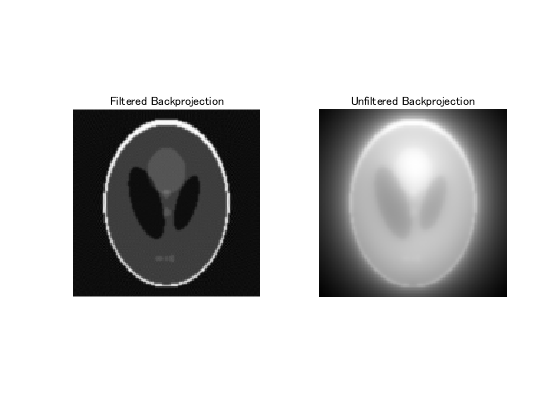

figure
subplot(1,2,1)
imshow(I1,[])
title('Filtered Backprojection')
subplot(1,2,2)
imshow(I2,[])
title('Unfiltered Backprojection')

© Copyright, Shogo MURAMATSU, All rights reserved.